# Exercise 1

## Exercise 1.1

clear all;
clc;
close all;

% Setup parameters for Problem
sim_name = 'concentration_1_1';
plt_title = 'numerical vs analytical solution 1.1';
h = 1;
N = 100;
dt = 0.00004;
numberSteps = 1000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% Set boundary condition at x=0
C(1) = 1;

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_explicit(C,s,1);
    
    if makeVideo && mod(i,30)==0
        C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params, C_analytic)
    end
    
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


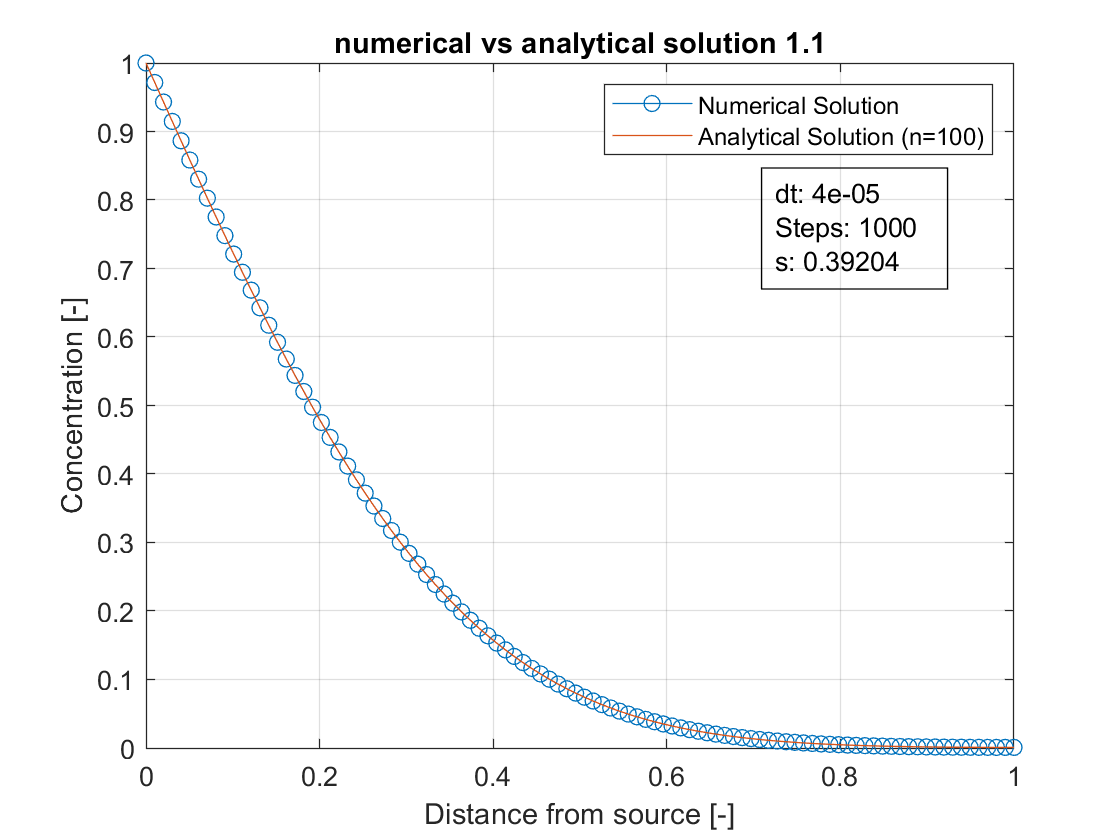


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_analytic);

## Exercise 1.2

clear all;
clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_2';
plt_title = 'numerical solution 1.2';
h = 1;
N = 100;
dt = 0.00005;
numberSteps = 10000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% Set boundary condition at x=0
C(1) = 1;
% Set boundary condition at x=h
C(end) = 0;
if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_explicit(C,s,2);
    
    if makeVideo && mod(i,30)==0
        %C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params)%, C_analytic)
    end
    
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


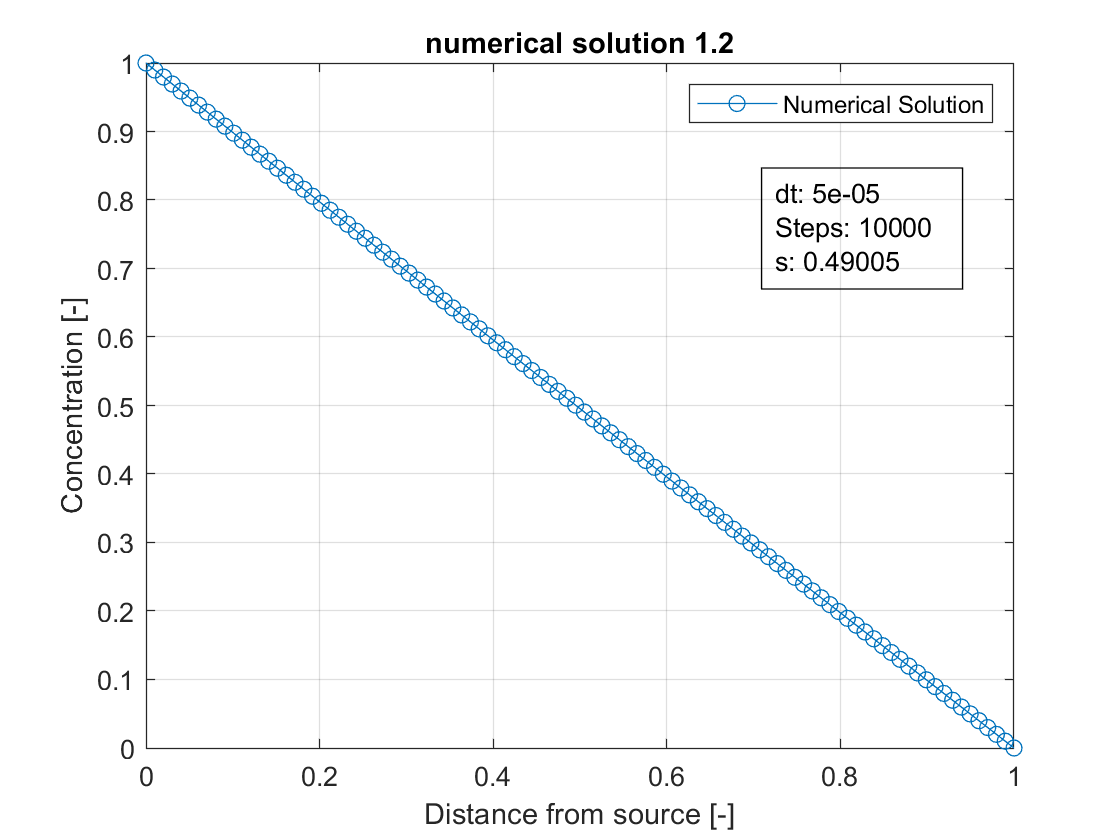


try
    close(v);
end

% Plot final solution
%C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params)%, C_analytic);

## Exercise 1.3

clear all;
clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_3';
plt_title = 'numerical solution 1.3'

plt_title = 'numerical solution 1.3'

h = 1;
N = 100;
dt = 0.0005;
numberSteps = 1000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2

s = 4.9005


% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);

% Diagonal for update matrix
diag = ones(1,N-1)*(1+2*s);
lower = ones(2,N-1)*(-s); % lower diag
upper = ones(1,N-1)*(-s); % upper diag
% Setup boundary condition at x=0
C(1) = 1;
diag(1) = 1; % ==Keep C(1) always the same
upper(1) = 0; % ==Keep C(1) always the same
% Setup boundary condition at x=h
diag(end) = 1+s; % ==Keep C(end) always the same

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
start = now();
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_implicit_new(C, N, diag, lower, upper);
    %C = makeTimeStep_implicit(C, s);
    if makeVideo && mod(i,30)==0
        %C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params)%, C_analytic)
    end
    
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


runtime = now() - start

runtime = 1.5162e-06

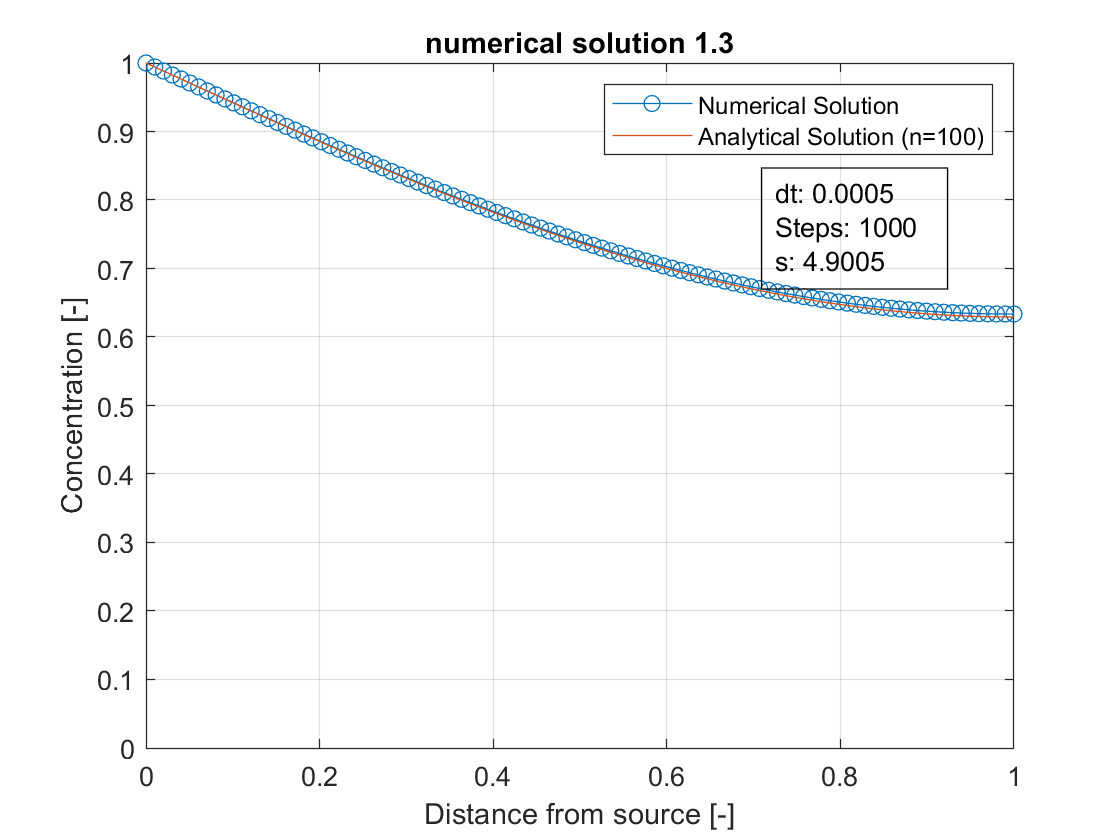

try
close(v);
end

% Plot final solution
C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_analytic);

## Exercise 1.4

%clear all;
%clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_4_halftime'; % name for movie
plt_title = 'numerical solution 1.4'

plt_title = 'numerical solution 1.4'

h = 1;
N = 100;
dt = 0.0005;
numberSteps = 1000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2

s = 4.9005


% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
C_check = zeros(1,N);

% Diagonal for update matrix
diag = ones(1,N-1)*2*(1+s);                         %%%%%%% changed something here
% Modified diagonal
% diag = ones(1,N-1)*2*(1+s);
lower = ones(2,N-1)*(-s); % lower diag
upper = ones(1,N-1)*(-s); % upper diag

% Set boundary condition at x=0
C(1) = 1;
diag(1) = 1; % ==Keep C(1) always the same
upper(1) = 0; % ==Keep C(1) always the same
% Set boundary condition at x=h
diag(end) = 2+s; % ==Keep C(1) always the same      %%%%%%%%% changed something here

%%%%%%%%%%%%%%%%%%%%%% Setup for 1.3 to compare
% Setup vectors/arrays
C_1_3 = zeros(1,N);

% Diagonal for update matrix
diag_1_3 = ones(1,N-1)*(1+2*s);
lower_1_3 = ones(2,N-1)*(-s); % lower diag
upper_1_3 = ones(1,N-1)*(-s); % upper diag
% Setup boundary condition at x=0
C_1_3(1) = 1;
diag_1_3(1) = 1; % ==Keep C(1) always the same
upper_1_3(1) = 0; % ==Keep C(1) always the same
% Setup boundary condition at x=h
diag_1_3(end) = 1+s; % ==Keep C(end) always the same
%%%%%%%%%%%%%%%%%%%%%% end of setup for 1.3 to compare

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

error_1_3 = ones(1,numberSteps);
error_1_4 = ones(1,numberSteps);
% SIMULATION
start = now();
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    
    C = makeTimeStep_CrankNicolson(C, diag, lower, upper, sim_params);
    C_1_3 = makeTimeStep_implicit_new(C_1_3, N, diag_1_3, lower_1_3, upper_1_3);
    C_analytic = analyticalSolution(N,1000,i*dt);
    error_1_3(i) = sum(abs(C_analytic-C_1_3))/N;
    error_1_4(i) = sum(abs(C_analytic-C))/N;
    
    if makeVideo && mod(i,30)==0
        C_analytic = analyticalSolution(N,100,i*dt*2);
        writeFrame(v, C, x, i, sim_params, C_analytic)
    end  
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


runtime = now() - start

runtime = 3.8646e-05

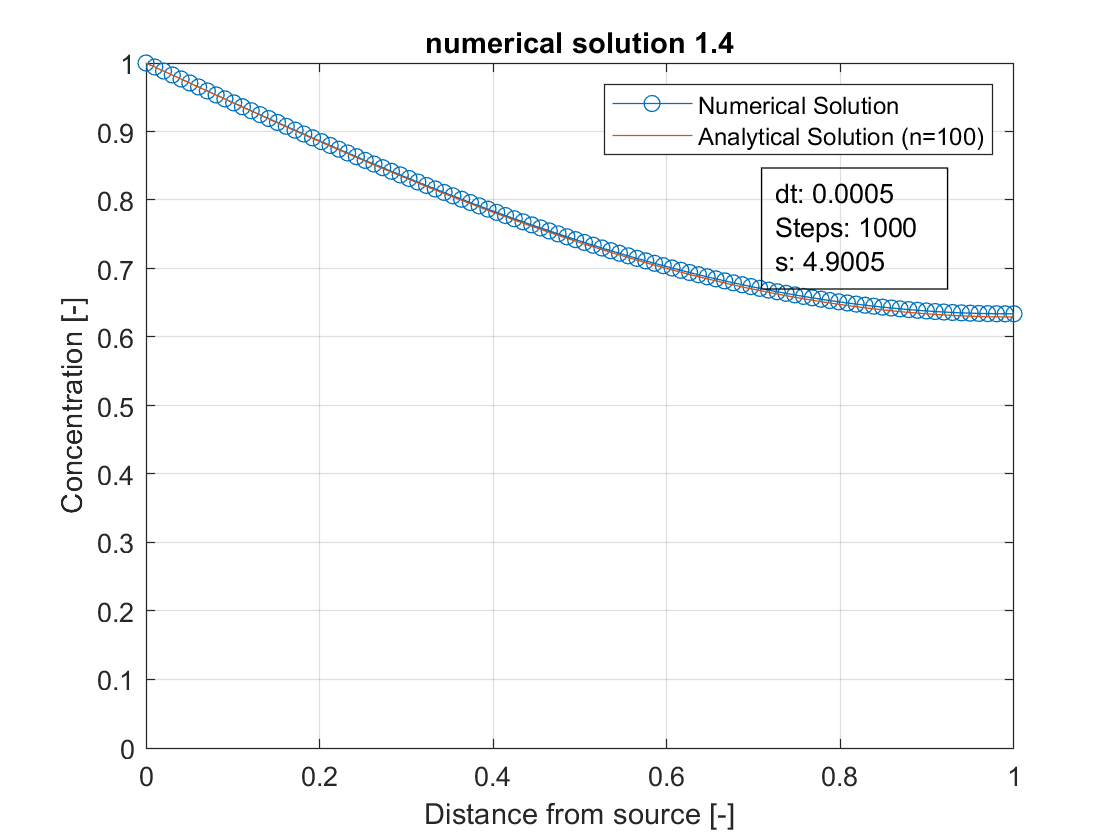


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_analytic);

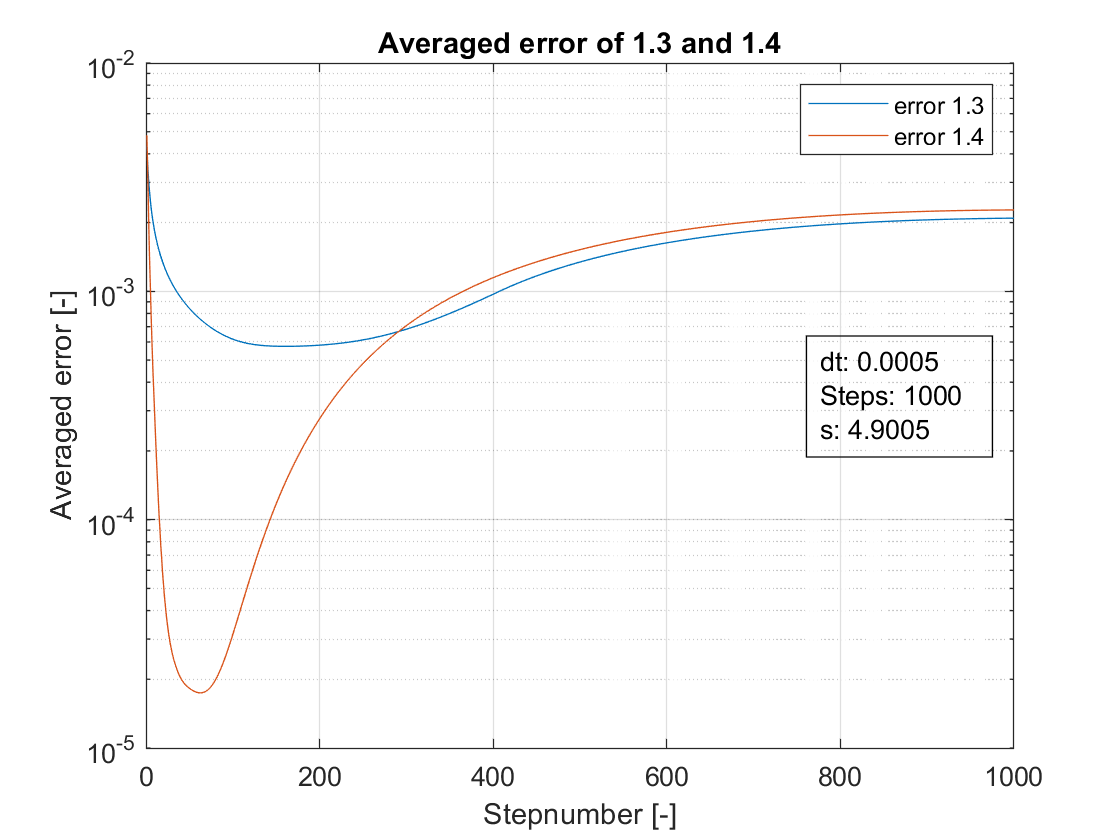


figure
semilogy(1:numberSteps,error_1_3);
hold on;
semilogy(1:numberSteps,error_1_4);
dim = [0.72 0.3 0.3 0.3];
str = {['dt: ' num2str(dt)], ['Steps: ' num2str(numberSteps)], ['s: ' num2str(s)]};
annotation('textbox',dim,'String',str,'FitBoxToText','on');
grid on;
legend('error 1.3', 'error 1.4','Location','northeast')
title('Averaged error of 1.3 and 1.4')
xlabel('Stepnumber [-]')
ylabel('Averaged error [-]')

#### A note on the Crank-Nichelson-Algorithm:

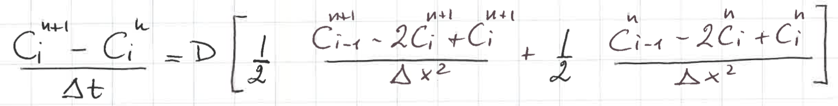

according to lecure should be:


$$\frac{C_i^{n+1} - C_i^n}{\Delta t} = \frac{D}{2} \left ( \frac{C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1}}{\Delta x^2}  + \frac{C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1}}{\Delta x^2} \right)$$


$D=1$ for simplicites sake


$$\Delta t / \Delta x^2 = s$$



$$2 (C_i^{n+1} - C_i^n) = s \dot \left ( C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1} + C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1} \right)$$


After rearranging, however, I get this:


$$- s C_{i-1}^{n+1} + 2(1+s) C_i^{n+1}  -  s C_{i-1}^{n+1} = s C_{i-1}^{n} + 2(1-s) C_i^{n} + s C_{i-1}^{n}$$


Hmm...thats a bit different. It also doesn't work :D

## Exercise 2.1

clear all;
clc;
close all;

sim_name = 'concentration_2_1_square';
plt_title = 'numerical solution 2.1.square';
h = 1;
N = 101;
dt = 0.011;
numberSteps = 65;
makeVideo = false;

dx = 1/(N-1);
C0 = dt/dx;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.C0 = C0;
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

x = linspace(0,h,N);
C = zeros(1,N);
for i = 0:1:100
    if (i > 10 & i < 30)
        C(i) = 1;
    end
end
Cstart = C;

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

for i = 1:numberSteps
   if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_upwind(C,C0);
    
    if makeVideo
        C_analytic = analyticalSolutionAdvection(Cstart,i);
        writeFrameAdvection(v, C, x, i, sim_params, C_analytic, [-1 2])
    end
    
end

20.00 %
40.00 %
60.00 %
80.00 %
100.00 %


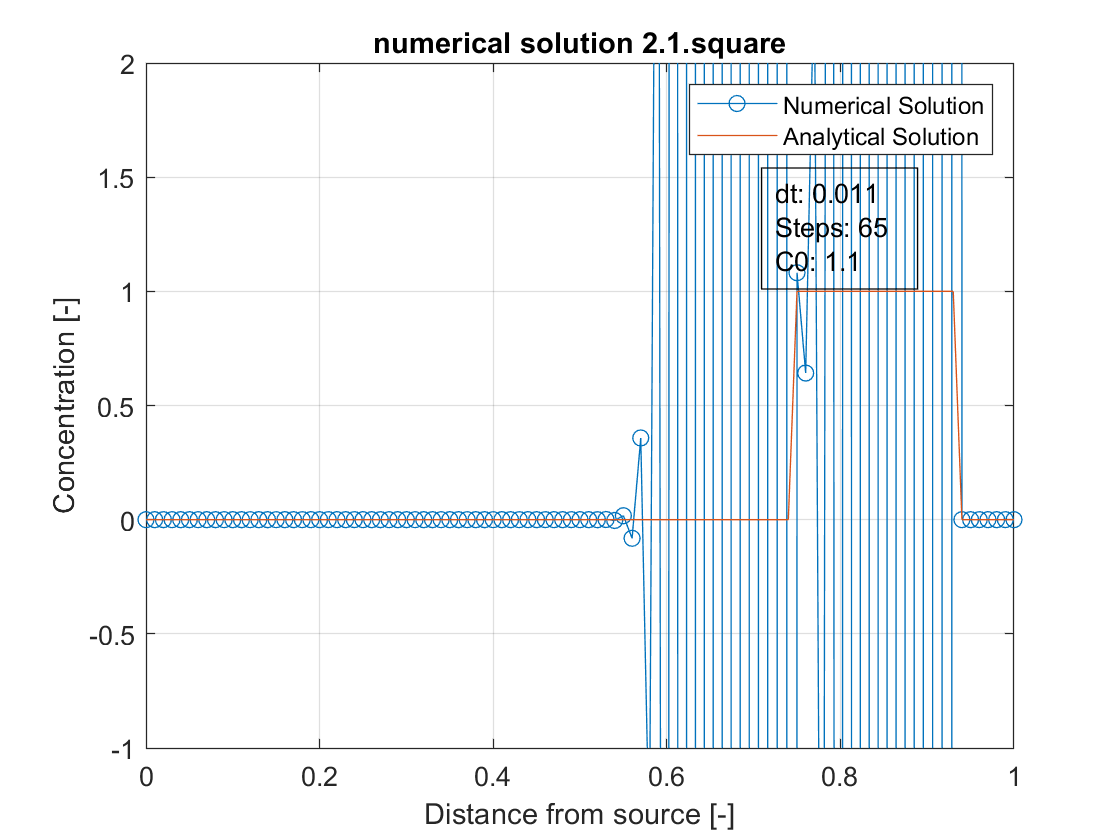


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolutionAdvection(Cstart,numberSteps);
plotConcentrationAdvection(x, C, sim_params, C_analytic, [-1 2]);



%% part two

sim_params.plt_title = 'numerical solution 2.1.gaussian';
t = x;
C = exp(-10.*(4.*t-1).^2);
Cstart = C;

if makeVideo
    v = VideoWriter('concentration_2_1_gauss');
    open(v);
end

C0 = dt/dx;
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_upwind(C,C0);
    
    if makeVideo
        C_analytic = analyticalSolutionAdvection(Cstart,i);
        writeFrameAdvection(v, C, x, i, sim_params, C_analytic, [-1 2])
    end
    
end

20.00 %
40.00 %
60.00 %
80.00 %
100.00 %


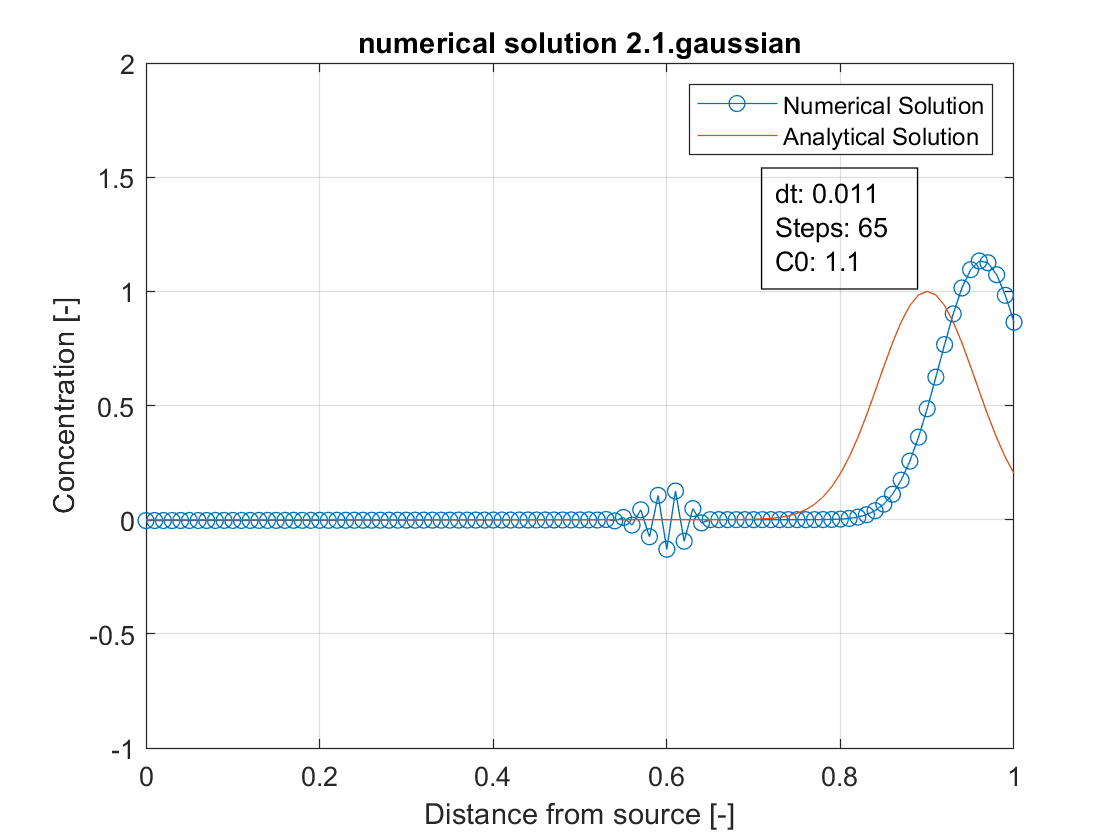


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolutionAdvection(Cstart,numberSteps);
plotConcentrationAdvection(x, C, sim_params, C_analytic, [-1 2]);